# Generate a Simulink Thermal Model from Motor-CAD

Run this script to automatically import Motor-CAD™ files into MATLAB® and generate a Simulink® reduced-order thermal model (ROM).

You need Motor-CAD v15 (or higher) installed, with Python scripting enabled (see Motor-CAD documentation).

## Overview of the MATLAB interface to Motor-CAD

This script uses an object-oriented MATLAB interface to Motor-CAD. The interface is open-source and is included in this example (see the `mcadinterface` package).

The package comprises a `BasicInterface.m` class file and a `ThermalInterface.m` class file. The `BasicInterface` implements basic Motor-CAD commands available in the PyMotorCAD Command list. The `ThermalInterface` extends the `BasicInterface` with additional commands that are useful to automate common workflows on the *Thermal* context of Motor-CAD.

You can edit the interface to customize it, extend it, and improve it. It can help you automate your Motor-CAD workflows.

Import an IPMSM with Housing Water Jacket and Self-Ventilated cooling, based on the `e8_eMobility_IPM` Motor-CAD template.

motFile = fullfile('data', 'e8_IPMSM_HWJandVent.mot');
McadIntf = mcadinterface.ThermalInterface(motFile);

Display properties of the motor interface and open the class documentation:

disp(McadIntf)

  ThermalInterface with properties:

                            workingDirectory: 'L:\PROJECTS\Dev21b\import-thermal-motorcad\data'
                              mcadROMLibName: 'mcadROM_lib'
                                   NodeNames: {123×1 cell}
                         NodeNamesAndMcadIdx: {123×2 cell}
                      GroupNamesAndMcadIdxes: {12×2 cell}
              CoolingSystemNamesAndMcadIdxes: {2×2 cell}
                                   Speed_Mat: [39×60 double]
                            Shaft_Torque_Mat: [39×60 double]
                      Stator_Copper_Loss_Mat: [39×60 double]
                         Rotor_Cage_Loss_Mat: [39×60 double]
              Iron_Loss_Stator_Back_Iron_Mat: [39×60 double]
                  Iron_Loss_Stator_Tooth_Mat: [39×60 double]
                         Stray_Load_Loss_Mat: [39×60 double]
                             Magnet_Loss_Mat: [39×60 double]

doc(McadIntf)

Motor-CAD discretizes the motor in nodes. Each node has a name and Motor-CAD index:

McadIntf.NodeNamesAndMcadIdx

ans = 123×2 cell array
    {'Ambient'       }    {[ 0]}
    {'Housing'       }    {[ 1]}
    {'Housing_OH_F'  }    {[ 2]}
    {'Housing_F'     }    {[ 3]}
    {'Endcap_F'      }    {[ 4]}
    {'Housing_OH_R'  }    {[ 6]}
    {'Housing_R'     }    {[ 7]}
    {'Endcap_R'      }    {[ 8]}
    {'Stator_Yoke'   }    {[ 9]}
    {'Stator_Surface'}    {[11]}
    {'Rot_Surface'   }    {[12]}
    {'Magnet'        }    {[13]}
    {'Rot_Lam_Yoke'  }    {[15]}
    {'Shaft_Centre'  }    {[16]}
    {'Shaft_F'       }    {[17]}
    {'Shaft_R'       }    {[18]}


You can set parameter values in MotorCAD from MATLAB. Set the shaft speed to 3000 rpm and the ambient temperature to 15 degC. Observe how Motor-CAD has been updated.

McadIntf.Shaft_Speed_RPM = 3000;
McadIntf.Tambient_degC = 20;

The `updateModel()` method updates the derived interface properties (the state-space matrices, cooling system properties, and loss tables) corresponding to the current parameter values.

updateModel(McadIntf);

Now you can get the updated Motor-CAD thermal state-space matrices corresponding to 3000 rpm and 15 degC ambient temperature:

McadIntf.ResMat; % Resistance matrix
McadIntf.CapMat; % Capacitance matrix
McadIntf.Amat; % State-space A matrix
McadIntf.Bmat; % State-space B matrix

The state-space model equation is:


$$\frac{\textrm{dx}}{\textrm{dt}}\;=\;A\;x+B\;p$$


where:

- ***x*** is the vector of node temperatures (the states)

- ***p*** is the vector of node losses

- ***A*** and ***B*** are the state-space matrices, computed from the resistance and capacitance matrices.

You can get a list of the enabled cooling systems and the corresponding Motor-CAD indices of their thermal nodes:

McadIntf.CoolingSystemNamesAndMcadIdxes

ans = 2×2 cell array
    {'Ventilated'          }    {[52 53 54 55 56 57 59 60 128 129 131 434 435 809 810]}
    {'Housing Water Jacket'}    {[                                     29 132 404 779]}


You can plot the cooling systems flow graphs:

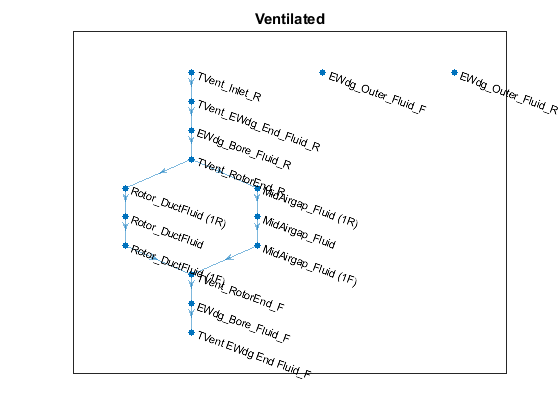

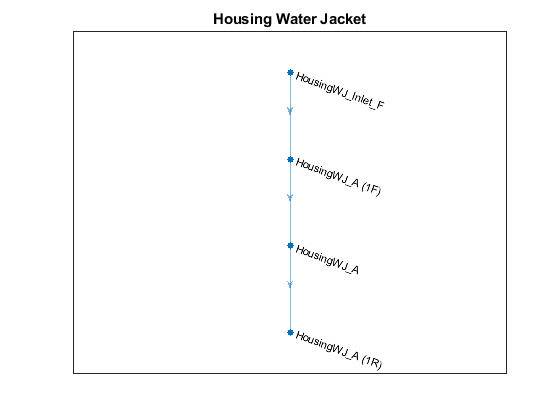

coolDigraphs = {McadIntf.CoolingSystemsDigraphs(McadIntf.EnabledCoolingSystems).Digraph};
for idx = 1:length(coolDigraphs)
    coolingName = McadIntf.CoolingSystemNamesAndMcadIdxes{idx,1};
    figure();   
    graphPlot = coolDigraphs{idx}.plot();
    graphPlot.Interpreter = 'none'; % avoid subscript labels
    set(graphPlot.Parent.Title, 'String', coolingName);
end

You can run steady-state calculations at a specified operating point (torque and speed) and get the temperatures for specific nodes of interest:

torque = 50; % Nm
speed = 4000; % rpm
McadIntf.runThermalSteadyStateWithSpecifiedTorqueSpeed(torque, speed)
mcadIdxs = [0,1,343,351,15,16, 13];
TssVec = McadIntf.getSteadyStateTemperatureForNodeMcadIdxs(mcadIdxs)

TssVec =    20.0000
   28.0540
   36.2278
   35.5302
   38.5916
   38.3919
   38.7277


The Motor-CAD Thermal Model lets you specify up to 24 different types of losses. You can get a list of the loss types and the corresponding value:

McadIntf.LossTypes

ans = 24×1 cell array
    {'Armature_Copper_Loss'                }
    {'Rotor_Copper_Loss'                   }
    {'Stator_Iron_Loss_Back_Iron'          }
    {'Stator_Iron_Loss_Tooth'              }
    {'Stator_Iron_Stray_Load_Loss'         }
    {'Rotor_Iron_Stray_Load_Loss'          }
    {'Stator_Copper_Stray_Load_Loss'       }
    {'Rotor_Copper_Stray_Load_Loss'        }
    {'Magnet_Iron_Loss'                    }
    {'Rotor_Iron_Loss_Embedded_Magnet_Pole'}
    {'Rotor_Iron_Loss_Back_Iron'           }
    {'Rotor_Iron_Loss_Tooth'               }
    {'Friction_Loss_F'                     }
    {'Friction_Loss_R'                     }
    {'Windage_Loss'                        }
    {'Windage_Loss_Ext_Fan'                }
    {'Armature_Copper_Freq_Component_Loss' }
    {'Main_Winding_Copper_Loss'            }
    {'Aux_Winding_Copper_Loss'             }
    {'Magnet_Banding_Loss'                 }
    {'Stator_Bore_Sleeve_Loss'             }
    {'Encoder_Loss'              

McadIntf.LossValues

ans =     20
     0
     0
     0
     0
     0
     0
     0
     0
     0


You can run transient calculations with specified losses of each type in the Motor-CAD Thermal Model, and get the temperature time series for specific nodes of interest:

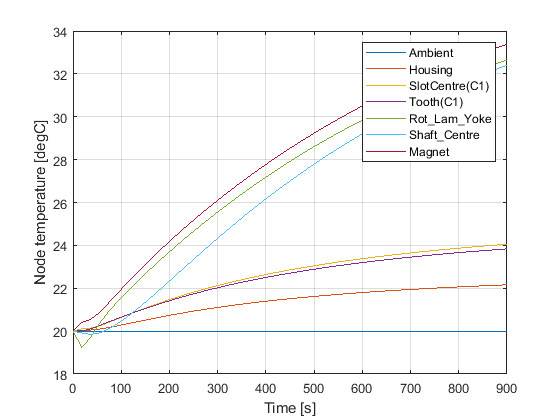

lossVec = 25*ones(24,1); % 25 Watts for each loss type
stopTime = 15*60; % [s] (15 mins)
numTimeSteps = 50;
McadIntf.runThermalTransientWithSpecifiedLosses(lossVec, stopTime, numTimeSteps);
[tVec, Tnodes] = McadIntf.getTransientTemperatureForNodeMcadIdxs(mcadIdxs);
McadIntf.plotTransientTemperatureForNodeMcadIdxs(mcadIdxs);

You can also run transient calculations with specified torque and speed, using loss maps in the Motor-CAD Lab Model:

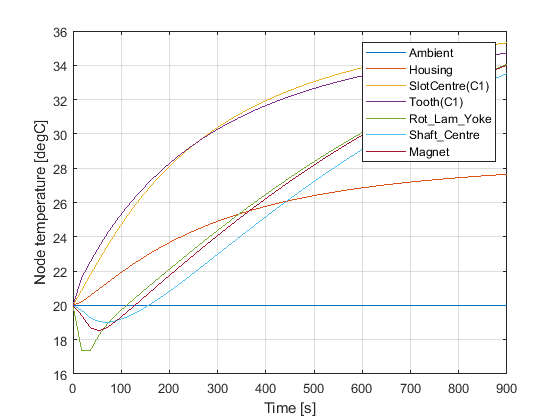

McadIntf.runThermalTransientWithSpecifiedTorqueSpeed(torque, speed, stopTime, numTimeSteps)
McadIntf.plotTransientTemperatureForNodeMcadIdxs(mcadIdxs);

Delete the interface object to close this Motor-CAD instance

delete(McadIntf);

## Import an Induction Motor with Housing Water Jacket

Having shown an overview of the Motor-CAD object-orientated interface, you can now use the interface to extract a reduced-order thermal model of a water-cooled induction motor.

Choose the motor file:

motFile1 = 'data/e5_IM_HWJ.mot'; % Motor-CAD file (*.mot)

Choose model parameter values:

Tambient_degC1 = 20; % Ambient temperature [degC]
% ROM interpolation breakpoints
Speed_Breakpoints_RPM1 = [200, 2000, 4000, 7000]; % Shaft speed [rpm] breakpoints
HWJ_FlowRate_Breakpoints_lpm1 = [3, 6, 10]; % Housing water jacket flow rate [lpm] breakpoints
HWJ_InletTemp_Breakpoints_degC1 = [20, 60]; % Housing water jacket inlet temperature [degC] breakpoints

Use the interface methods to generate the ROM:

e5_IM_HWJ = mcadinterface.ThermalInterface(motFile1);

% Set ambient temperature
e5_IM_HWJ.Tambient_degC = Tambient_degC1;
e5_IM_HWJ.updateModel();

% Specify Simulink model name
modelName = 'e5_IM_HWJ_ROM';
bdclose(modelName);
modelNamePath = findModelInProject(modelName);
if ~isempty(modelNamePath)
    delete(modelNamePath);
end
coolingSystemsEnabled = {'Housing Water Jacket'};

% Set ROM breakpoints in a structure
BkptsStruct = struct();
BkptsStruct.w = Speed_Breakpoints_RPM1;
BkptsStruct.fr1 = HWJ_FlowRate_Breakpoints_lpm1;
BkptsStruct.Tin1 = HWJ_InletTemp_Breakpoints_degC1;

tic;
e5_IM_HWJ.generateSimulinkReducedOrderModel(modelName, coolingSystemsEnabled, BkptsStruct);

Enabling the specified cooling systems...
Calculating state-space matrices for each breakpoint...
Breakpoint #1
  Speed = 200 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 20 degC
Breakpoint #2
  Speed = 200 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 60 degC
Breakpoint #3
  Speed = 200 rpm
  Housing Water Jacket flow rate = 6 lpm
  Housing Water Jacket inlet temperature = 20 degC
Breakpoint #4
  Speed = 200 rpm
  Housing Water Jacket flow rate = 6 lpm
  Housing Water Jacket inlet temperature = 60 degC
Breakpoint #5
  Speed = 200 rpm
  Housing Water Jacket flow rate = 10 lpm
  Housing Water Jacket inlet temperature = 20 degC
Breakpoint #6
  Speed = 200 rpm
  Housing Water Jacket flow rate = 10 lpm
  Housing Water Jacket inlet temperature = 60 degC
Breakpoint #7
  Speed = 2000 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 20 degC
Breakpoint #8
  Speed = 2000 rp

timeGenerate1 = toc

timeGenerate1 = 261.9513

saveModelInProject(modelName);

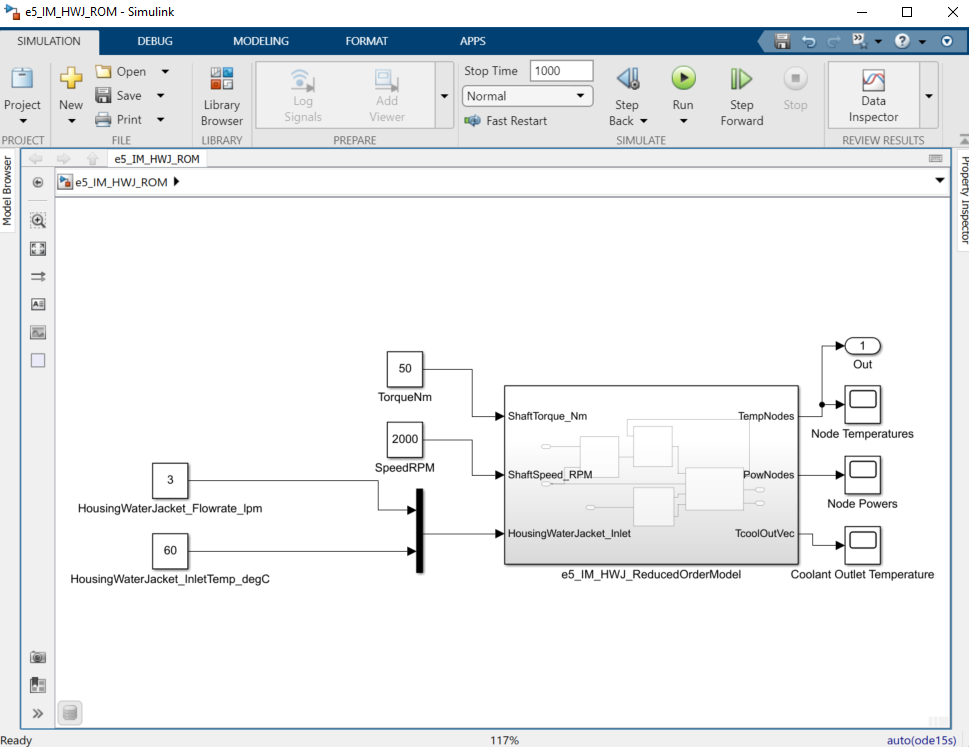

Delete the interface object to close this Motor-CAD instance

delete(e5_IM_HWJ);

## Import a PMSM with Housing Water Jacket and Ventilated

Similarly, you can use the interface to extract a reduced-order thermal model of PMSM motor with housing water jacket and self-ventilation.

Choose the motor file:

motFile2 = 'data/e8_IPMSM_HWJandVent.mot'; % Motor-CAD file (*.mot)

Choose model parameter values:

Tambient_degC2 = 25; % Ambient temperature [degC]
% ROM interpolation breakpoints
Speed_Breakpoints_RPM2 = [500, 3000, 7000]; % Shaft speed [rpm] breakpoints
HWJ_FlowRate_Breakpoints_lpm2 = [3, 10]; % Housing water jacket flow rate [lpm] breakpoints
HWJ_InletTemp_Breakpoints_degC2 = [20, 30, 40]; % Housing water jacket inlet temperature [degC] breakpoints
Vent_FlowRate_Breakpoints_lpm2 = [3, 10]; % Ventilated flow rate [lpm] breakpoints
Vent_InletTemp_Breakpoints_degC2 = [20, 30, 40]; % Ventilated inlet temperature [degC] breakpoints

Use the interface methods to generate the ROM:

e8_IPMSM_HWJandVent = mcadinterface.ThermalInterface(motFile2);

% Set ambient temperature
e8_IPMSM_HWJandVent.Tambient_degC = Tambient_degC2;
e8_IPMSM_HWJandVent.updateModel();

% Specify Simulink model name
modelName = 'e8_IPMSM_HWJandVent_ROM';
bdclose(modelName);
modelNamePath = findModelInProject(modelName);
if ~isempty(modelNamePath)
    delete(modelNamePath);
end
coolingSystemsEnabled = {'Housing Water Jacket', 'Ventilated'};

% Set ROM breakpoints in a structure
BkptsStruct = struct();
BkptsStruct.w = Speed_Breakpoints_RPM2;
BkptsStruct.fr1 = HWJ_FlowRate_Breakpoints_lpm2;
BkptsStruct.fr2 = Vent_FlowRate_Breakpoints_lpm2;
BkptsStruct.Tin1 = HWJ_InletTemp_Breakpoints_degC2;
BkptsStruct.Tin2 = Vent_InletTemp_Breakpoints_degC2;

tic;
e8_IPMSM_HWJandVent.generateSimulinkReducedOrderModel(modelName, coolingSystemsEnabled, BkptsStruct);

Enabling the specified cooling systems...
Calculating state-space matrices for each breakpoint...
Breakpoint #1
  Speed = 500 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 20 degC
  Ventilated flow rate = 3 lpm
  Ventilated inlet temperature = 20 degC
Breakpoint #2
  Speed = 500 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 20 degC
  Ventilated flow rate = 3 lpm
  Ventilated inlet temperature = 30 degC
Breakpoint #3
  Speed = 500 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 20 degC
  Ventilated flow rate = 3 lpm
  Ventilated inlet temperature = 40 degC
Breakpoint #4
  Speed = 500 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 30 degC
  Ventilated flow rate = 3 lpm
  Ventilated inlet temperature = 20 degC
Breakpoint #5
  Speed = 500 rpm
  Housing Water Jacket flow rate = 3 lpm
  Housing Water Jacket inlet temperature = 30

timeGenerate2 = toc

timeGenerate2 = 840.8784

saveModelInProject(modelName);

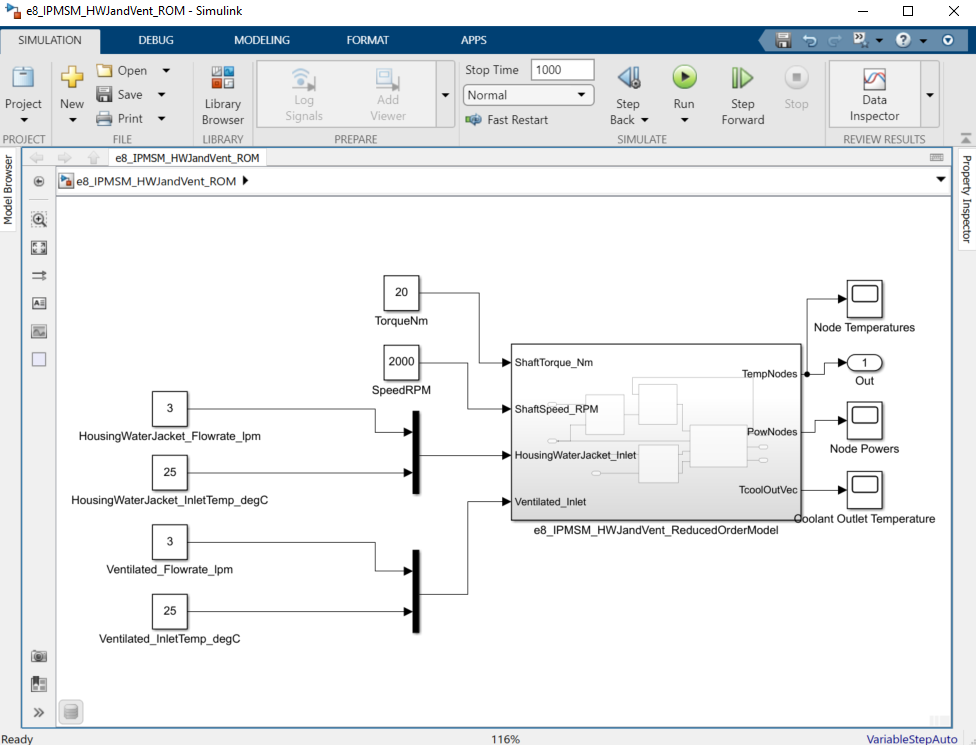

Delete the interface object to close this Motor-CAD instance

delete(e5_IM_HWJ);

Save workspace variables:

matFileNameToSave = "data/OutputFromGSTM.mat";
save(matFileNameToSave);

Utility functions

function saveModelInProject(modelName)
    theProject = matlab.project.rootProject;
    projectRootDir = theProject.RootFolder;
    save_system(modelName, fullfile(projectRootDir, 'models', strcat(modelName, '.slx')));
end

*Copyright 2022-2025 The MathWorks, Inc.*